clearvars

filename = 'gmshfile';
l = 1;
lc = 0.1;

create_unitcell(filename,l,lc)

Info    : Running 'gmsh gmshfile.geo -2' [Gmsh 4.8.4, 1 node, max. 1 thread]
Info    : Started on Mon Jun 07 18:50:37 2021
Info    : Reading 'gmshfile.geo'...
Info    : Done reading 'gmshfile.geo'
Info    : Meshing 1D...
Info    : [  0%] Meshing curve 1 (Line)
Info    : [ 30%] Meshing curve 2 (Line)
Info    : [ 50%] Meshing curve 3 (Line)
Info    : [ 80%] Meshing curve 4 (Line)
Info    : Done meshing 1D (Wall 0.000498772s, CPU 0s)
Info    : Meshing 2D...
Info    : Meshing surface 1 (Plane, Frontal-Delaunay)
Info    : Done meshing 2D (Wall 0.00449991s, CPU 0s)
Info    : 142 nodes 286 elements
Info    : Writing 'gmshfile.msh'...
Info    : Done writing 'gmshfile.msh'
Info    : Stopped on Mon Jun 07 18:50:37 2021 (From start: Wall 0.0145001s, CPU 0s)


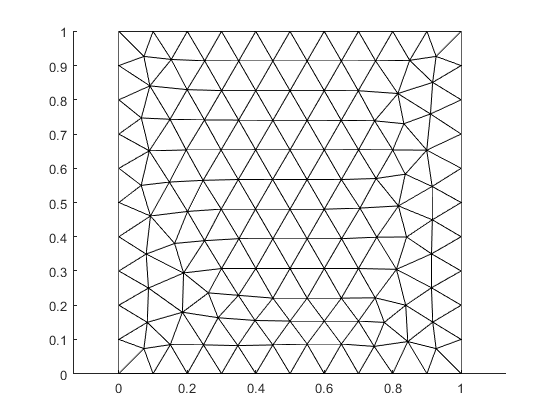


domainPid = 10;
[node, nids] = readnodes([filename,'.msh']);
conn = readelements([filename,'.msh'], domainPid);

plot_mesh(node,conn,'tria3')